Входные параметры

close all;
clear variables;
tic; % замер времени

#### 1.1 Исходные данные

% параметры волны
f = 400*10^6;
c = 3*10^8;
lambda = c/f*1000; % 0.75 м %%% убрать 
% /1000/lambda % перевод мм в м + в дилнаях волн

Задаим количество точек

N_cricle = 32; % точек на одну окружность
N_line = 100; % точек на одну сторону

% константы
k = 2*pi;
eta = 120*pi;
gamma = 1.781072417990;

% геометрические данные антенны
angle = 65;

#### 1.3. Расчет координат точек исходной фигуры

%% убрать
% lambda = 1000;

% исходные точки антенны
pl = struct('x', {}, 'y', {});
pl(1).x = 0/lambda;
pl(1).z = 0/lambda;
pl(2).x = 0/lambda;
pl(2).z = 14000/lambda;
pl(3).x = 7000/lambda;
pl(3).z = 14000/lambda;
pl(4).x = 7000/lambda;
pl(4).z = 0/lambda;

#### 1.3. Расчет координат точек окружностей

% точки окружностей
pc = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]});
pc(1).centr = [500, 13500]/lambda;
pc(1).r = 500/lambda;
pc(1).int1 = [0, 13500]/lambda;
pc(1).int2 = [500, 14000]/lambda;

pc(2).centr = [6500, 13500]/lambda;
pc(2).r = 500/lambda;
pc(2).int1 = [6500, 14000]/lambda;
pc(2).int2 = [7000, 13500]/lambda;

% исходные точки антенны
pli = struct('x', {}, 'y', {});
pli(1).x = 200/lambda;
pli(1).z = 0/lambda;
pli(2).x = 0/lambda;
pli(2).z = 13800/lambda;
pli(3).x = 6800/lambda;
pli(3).z = 13800/lambda;
pli(4).x = 6800/lambda;
pli(4).z = 0/lambda;

% точки окружностей
pci = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]});
pci(1).centr = [700, 13300]/lambda;
pci(1).r = 500/lambda;
pci(1).int1 = [200, 13500]/lambda;
pci(1).int2 = [700, 13800]/lambda;

pci(2).centr = [6300, 13300]/lambda;
pci(2).r = 500/lambda;
pci(2).int1 = [6300, 13800]/lambda;
pci(2).int2 = [6800, 13300]/lambda;

#### Получение контуро из функции

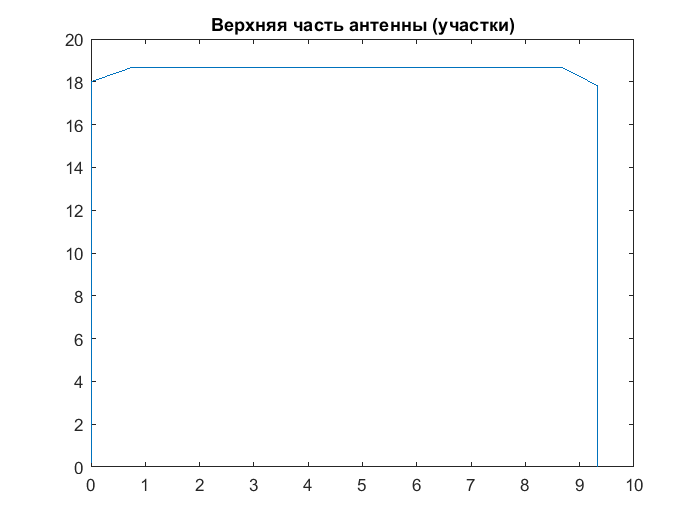

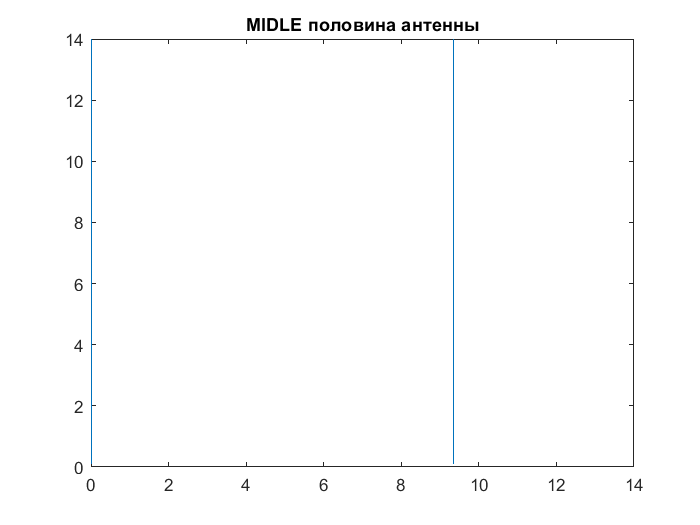

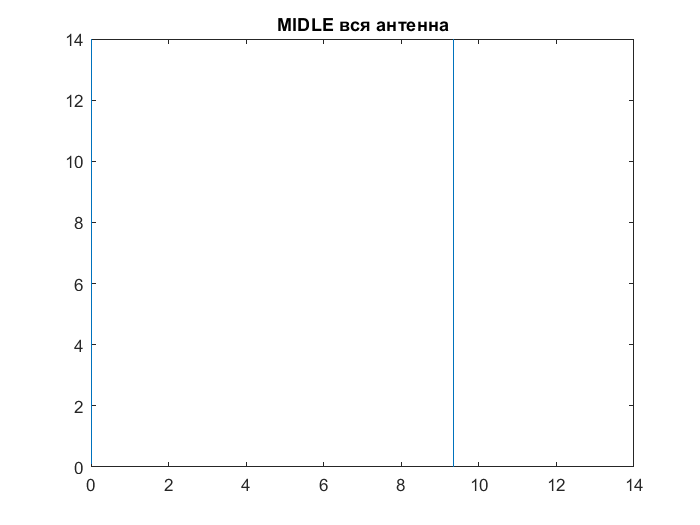

[x_midle, z_midle, dx, N] = contur(pl, pc, N_line, N_line);

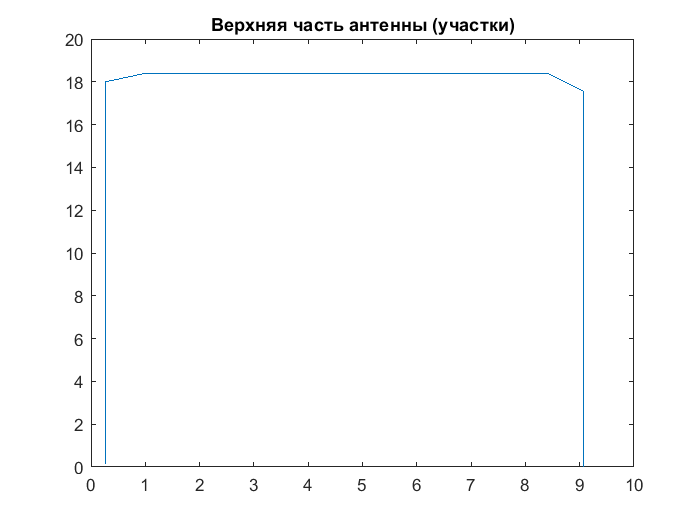

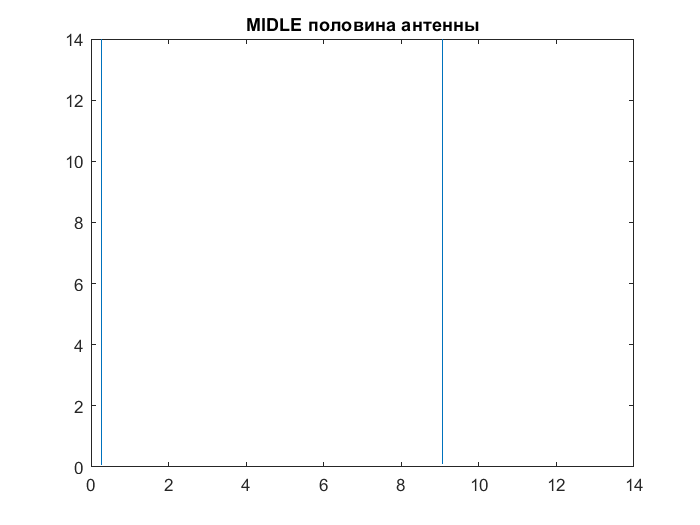

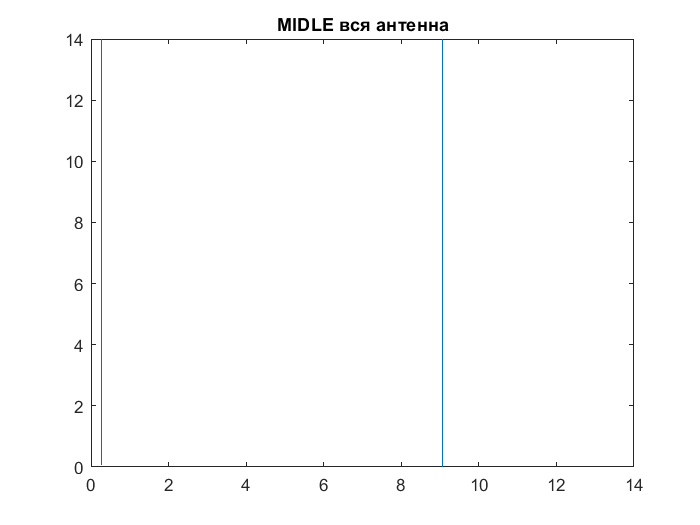

[x_midle_i, z_midle_i, dx_i, N_i] = contur(pli, pci, N_line, N_cricle);

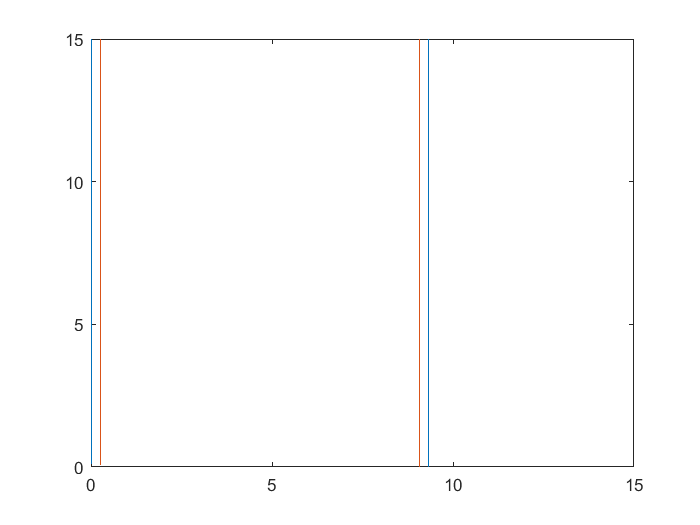


plot(x_midle, z_midle, x_midle_i, z_midle_i)
xlim([0, 15])
ylim([0, 15])

#### 1.5. Расчет координат излучателя

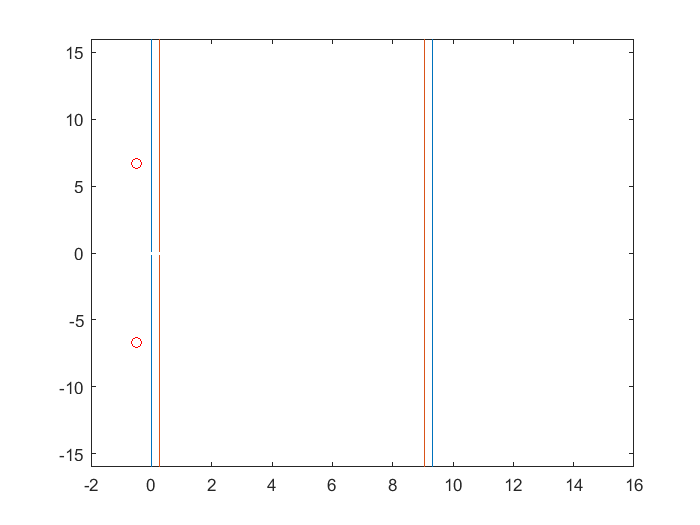

l1 = 22017/lambda;

% паарметры расположения
l_antenn = 5000/lambda; %%% убрать
h_antenn = 1/2; %%% убрать

% координаты самого излучателя
x1_antenn = - h_antenn;
z1_antenn = pl(2).x - l_antenn;

x2_antenn = x1_antenn;
z2_antenn = -z1_antenn;

plot(x_midle, z_midle, x_midle_i, z_midle_i, x1_antenn, z1_antenn, 'ro', x2_antenn, z2_antenn, 'ro');
xlim([-2.00 16.00])
ylim([-16 16.0])

#### 5.1. Падающее поле

% излучаель создает магнитное поле 
Ei = zeros(N,1);
Hi = zeros(N,1);
% падающее поле 
for m = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    
    % растояния 
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    % Падающее магнитное поле
    Hi(m) = besselh(0,1,k*r1) + besselh(0,1,k*r2);
end  

#### Сам алгоритм MAS

for m = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    
    %пробегаемся по всем точкам ВИ
    for n = 1 : N_i
        xn = x_midle_i(n);
        zn = z_midle_i(n);
        
        rmn = sqrt((xn-xm)^2 + (zn-zm)^2);
        
        Hs(m,n) = besselh(0,1,k*rmn);         
        
    end
end

% расчеток токов ВИ 
I=Hs\Hi;

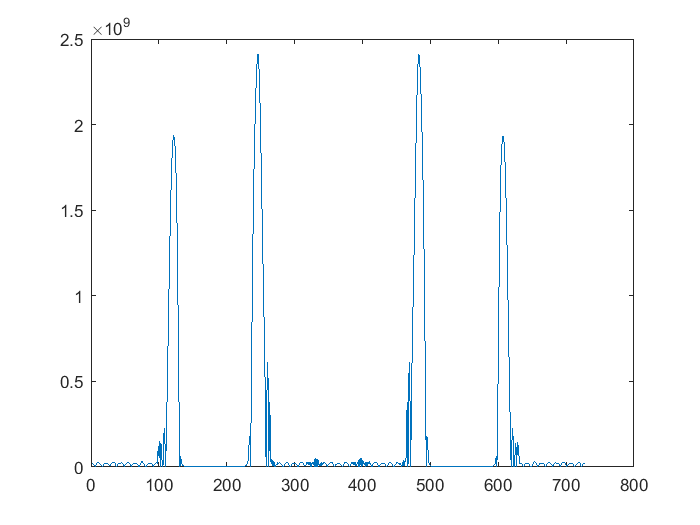


plot(1:length(I), abs(I));

#### 6.1. Где смотрим поле

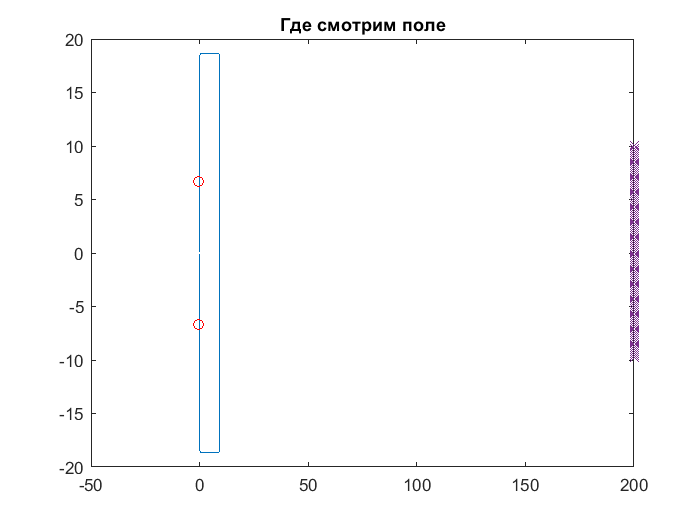

l = 150*10^3/lambda;
N_point = 100;
l_begin = -10;
l_end = 10;

x_see = zeros(1, N_point);
z_see = zeros(1, N_point);
for i = 1 : N_point
    step_see = (l_end - l_begin)/N_point;
    
    x_see(i) = l;
    z_see(i) = l_begin + step_see*i;
end

figure;
plot(x_midle,z_midle,x1_antenn,z1_antenn, '-ro', x2_antenn, z2_antenn, '-ro', x_see, z_see, 'x');
title('Где смотрим поле'); 

#### 6.2. Поле на растоянии без антенны

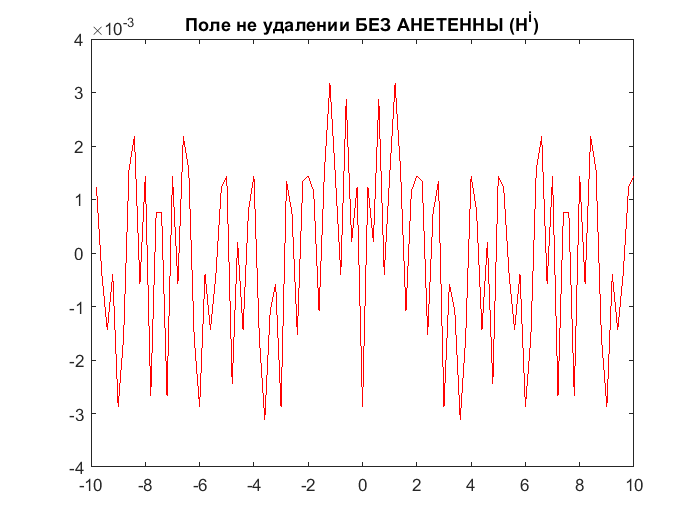

for m = 1 : N_point
    xm = x_see(m);
    zm = z_see(m);
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    Hi_without_antenn(m) = besselh(0,1,k*r1) + besselh(0,1,k*r2);
end

figure;
fig = plot(z_see, real(Hi_without_antenn), 'r');
title('Поле не удалении БЕЗ АНЕТЕННЫ (H^i)'); 

#### 6.2. Поле на растоянии с антеной

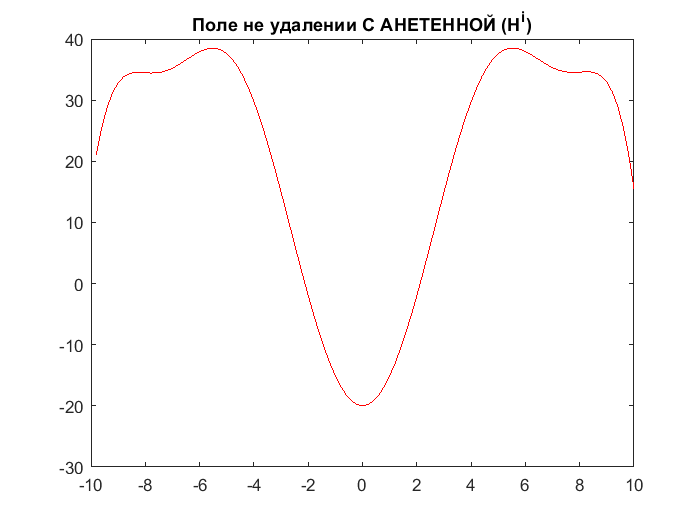

for m = 1 : N_point
    xm = x_see(m);
    zm = z_see(m);
    
    h_surf = 0;
    for n = 1 : N_i
        xn = x_midle_i(n);
        zn = z_midle_i(n);
        rmn = sqrt((xn-xm)^2 + (zn-zm)^2);
                
        h_surf = h_surf + I(n,1)*besselh(0,1,k*rmn);
    end
    H_surf(m) = h_surf;
end

figure;
fig = plot(z_see, real(H_surf), 'r');
title('Поле не удалении C АНЕТЕННОЙ (H^i)'); 

## ФУНКЦИЯ

function [x_midle, z_midle, dx, N] = contur(pl, pc, N_line, N_circle)

% массив исходныех точек
X_point = horzcat(pl(1).x, pl(2).x, pl(3).x, pl(4).x);
Z_point = horzcat(pl(1).z, pl(2).z, pl(3).z, pl(4).z);

#### Параметры окружностей

% первая окружность (1/4 окружности)
phi_1_begin = 0; % относительно оси х
phi_1_end = 90;
dphi_1 = 90;

% вторая окружность 
phi_2_begin = 90; % относительно оси х
phi_2_end = 180;
dphi_2 = 90;

#### Загоним все в массив

% Порядок точек
x1 = pl(1).x;
x2 = pc(1).int1(1);
x3 = pc(1).int2(1);
x4 = pc(2).int1(1);
x5 = pc(2).int2(1);
x6 = pl(4).x;
% 
z1 = pl(1).z;
z2 = pc(1).int1(2);
z3 = pc(1).int2(2);
z4 = pc(2).int1(2);
z5 = pc(2).int2(2);
z6 = pl(4).z; 

% длины отрезков каждого участков
l12 = sqrt((x1 - x2)^2 + (z1 - z2)^2); 
l23 = 2*pi*pc(1).r;
l34 = sqrt((x3 - x4)^2 + (z3 - z4)^2);
l45 = 2*pi*pc(2).r;
l56 = sqrt((x5 - x6)^2 + (z5 - z6)^2);

#### 1.4. Количество точек на антенне

% точки на прямых
N12 = N_line;
N34 = N12;
N56 = N12;
N1_t = N_circle;
N2_t = N1_t;

% N12 = round(l12,-1)*100*alpha;
% N23 = round(l23,-1)*100*alpha;
% N34 = round(l34,-1)*100*alpha;
% N45 = round(l45,-1)*100*alpha;
% N56 = round(l56,-1)*100*alpha;
% N1_t = N23*alpha;
% N2_t = N45*alpha;

% cуммареное количество точек на антенне
N = 2*(N12 + N34 + N56) + 2*(N1_t + N2_t); 

#### Построение окружностей

%%% Построим дугу окружности 1

R1 = pc(1).r;
% угловой шаг окружности
for i = 1 : N1_t
    phid_step = dphi_1/N1_t;
    t1(i) = phid_step*i;
    dx23(i) = 2*R1*sind(dphi_1/2);
end

x1_c = pc(1).centr(1);
z1_c = pc(1).centr(2);

x23_r = R1*cosd(-t1+180) + x1_c;
z23_r = R1*sind(-t1+180) + z1_c;

% figure;
% plot(x23_r, z23_r,'g')
%%% Построим дугу окружности 2

R2 = pc(2).r;

% угловой шаг окружности
for i = 1 : N2_t
    phid_step = dphi_2/N2_t;
    t2(i) = phi_2_begin + phid_step*i;
    dx45(i) = 2*R2*sind(dphi_2/2);
end

x2_c = pc(2).centr(1);
z2_c = pc(2).centr(2);

x45_r = R2*cosd(-t2+180) + x2_c;
z45_r = R2*sind(-t2+180) + z2_c;

% figure;
% plot(x45_r, z45_r,'g')

#### 2.1 Антена над землей

%% УЧАСТОК_1 - наклонный участок
dx_12 = l12/N12;

% заполнение масивов
for i = 1 : N12
    step23 = dx_12*i;
    x12(i) = x1;
    z12(i) = z1 + step23;
    dx12(i) = dx_12;
end

%% УЧАСТОК 2 - горизонтальный участок
dx_34 = l34/N34;

% заполнение масивов
for i = 1 : N34
    step34 = dx_34*i;
    x34(i) = x3 + step34;
    z34(i) = z3;
    dx34(i) = dx_34;
end

%% УЧАСТОК 3 - вниз
dx_56 = l56/N56;

for i = 1 : N56
    step56 = dx_56*i;
    x56(i) = x5;
    z56(i) = z5 - step56;
    dx56(i) = dx_56;
end

% cклеим все вместе 
X_l = horzcat(x12,x34,x56);
Z_l = horzcat(z12,z34,z56);

figure;
plot(X_l,Z_l)
title("Верхняя часть антенны (участки)")

#### ОБЩИЙ DX

dx = horzcat(dx12, dx23, dx34, dx45, dx56);
dx = horzcat(dx, flip(dx));

#### 2.2 Вся антена (границы участков)

% АНТЕННА ПОД ЗЕМЛЕЙ границы участков

X_all = [x12, x23_r, x34, x45_r, x56];
Z_all = [z12, z23_r, z34, z45_r, z56];

Антенная центры участков 

% % ПРЯМЫЕ
%% УЧАСТОК_1 - наклонный участок
for i = 1 : N12
    step23 = dx_12*(i-0.5);
    x12_midle(i) = x1;
    z12_midle(i) = z1 + step23;
end

%% УЧАСТОК 2 - горизонтальный участок
for i = 1 : N34
    step34 = dx_34*(i-0.5);
    x34_midle(i) = x3 + step34;
    z34_midle(i) = z3;
end

%% УЧАСТОК 3 - вниз
for i = 1 : N56
    step56 = dx_56*(i-0.5);
    x56_midle(i) = x5;
    z56_midle(i) = z5 - step56;
end
% % ОКРУЖНОСТИ
%%% Построим дугу окружности 1
for i = 1 : N1_t
    phid_step = dphi_1/N1_t;
    t1(i) = phid_step*(i-0.5);
end

x23_midle = R1*cosd(-t1+180) + x1_c;
z23_midle = R1*sind(-t1+180) + z1_c;

%%% Построим дугу окружности 2
for i = 1 : N2_t
    phid_step = dphi_2/N2_t;
    t2(i) = phi_2_begin + phid_step*(i-0.5);
end

x45_midle = R2*cosd(-t2+180) + x2_c;
z45_midle = R2*sind(-t2+180) + z2_c;


% АНТЕННА ПОД ЗЕМЛЕЙ центры участков

x_midle = [x12_midle, x23_midle, x34_midle, x45_midle,...
         x56_midle];
z_midle = [z12_midle, z23_midle, z34_midle, z45_midle,...
         z56_midle];

figure;
plot(x_midle, z_midle)
title("MIDLE половина антенны")

xlim([0,14])
ylim([0,14])

x_midle = horzcat(x_midle, flip(x_midle));
z_midle = horzcat(z_midle, flip(-z_midle));

figure;
plot(x_midle, z_midle)
xlim([0,14])
ylim([0,14])
title("MIDLE вся антенна")

end